# REGALS analysis of NrdE AEX data

**The data and analysis were originally published in:**

Mackenzie J. Parker, Ailiena O. Maggiolo, William C. Thomas, Albert Kim, Steve P. Meisburger, Nozomi Ando, Amie K. Boal, JoAnne Stubbe. *An endogenous dAMP ligand in Bacillus subtilis class Ib RNR promotes assembly of a noncanonical dimer for regulation by dATP. *PNAS, May 2018, 115 (20), E4594-E4603; DOI: 10.1073/pnas.1800356115

addpath('../matlab/'); % add REGALS code to path

## Load data

load data/NrdE_mix_AEX.mat q I sigma name
fprintf(1,'loaded dataset: %s\n',name);

loaded dataset: RNR_AEX/NrdE_mix_AEX_1_31


x = 1:size(I,2); % x is the frame number

## Set up REGALS calculation

Each component has a concentration and profile regularizer. In this case, there is no regularization of the profiles (all are "simple" type).

Bg1 = Component(...
    Concentration(x,'smooth',...
        'xmin',min(x)-1E-3,...
        'xmax',max(x)+1E-3,...
        'isZeroAtXmin',false,...
        'isZeroAtXmax',false),...
    Profile(q,'simple'));

Bg2 = Component(... %
    Concentration(x,'smooth',...
        'xmin',201-1E-3,...
        'xmax',max(x)+1E-3,...
        'isZeroAtXmin',true,...
        'isZeroAtXmax',false),...
    Profile(q,'simple'));

C1 = Component(...
    Concentration(x,'smooth',...
        'xmin',730,...
        'xmax',1270),...
    Profile(q,'simple'));

C2 = Component(...
    Concentration(x,'smooth',...
        'xmin',1150,...
        'xmax',1600),...
    Profile(q,'simple'));

% create Mixture object and set regularization parameters.
M = Mixture([C1,C2,Bg1,Bg2]);


## Run REGALS

R = REGALS(I,sigma); % creat REGALS object

M.concentrationLambda = M.estimateConcentrationLambda(sigma,[Inf,Inf,8,8]);
%M = R.autoEstimateLambda(M); % NEW! (to try, uncomment and run)

% set stopFun to return true when 50 iterations is exceeded
stopFun = @(iter,params) deal(iter >=  50,'maxIter');

updateFun = @(iter,NewMix,params,resid) ...
    fprintf(1,'%2d, x2 = %f, delta_profile = %s\n',...
    iter,params.x2,mat2str(params.delta_profile,3));

% run for 50 iterations
[M1,params,resid] = R.run(M,stopFun,updateFun);

 1, x2 = 1.122819, delta_profile = [360 362 84 57.5]
 2, x2 = 1.046630, delta_profile = [5.24 2.17 23.5 41.3]
 3, x2 = 1.025449, delta_profile = [2.3 0.597 9.02 11]
 4, x2 = 1.017819, delta_profile = [1.8 0.452 7.92 3.49]
 5, x2 = 1.015064, delta_profile = [1.07 0.264 4.89 1.69]
 6, x2 = 1.013981, delta_profile = [0.677 0.154 2.67 1.06]
 7, x2 = 1.013488, delta_profile = [0.466 0.094 1.29 1.22]
 8, x2 = 1.013225, delta_profile = [0.335 0.0593 0.531 1.46]
 9, x2 = 1.013060, delta_profile = [0.253 0.0384 0.142 1.62]
10, x2 = 1.012943, delta_profile = [0.196 0.0258 0.0644 1.71]
11, x2 = 1.012850, delta_profile = [0.153 0.0178 0.146 1.75]
12, x2 = 1.012771, delta_profile = [0.119 0.0126 0.185 1.77]
13, x2 = 1.012700, delta_profile = [0.0925 0.00909 0.202 1.77]
14, x2 = 1.012634, delta_profile = [0.0723 0.00681 0.207 1.77]
15, x2 = 1.012571, delta_profile = [0.0569 0.00537 0.206 1.77]
16, x2 = 1.012510, delta_profile = [0.0451 0.00437 0.203 1.76]
17, x2 = 1.012452, delta_profile = [0.0361 0

## Extract the two particle components

[I1,sigma1] = M1.extractProfile(I,sigma,1);
[I2,sigma2] = M1.extractProfile(I,sigma,2);

## Plot the end results

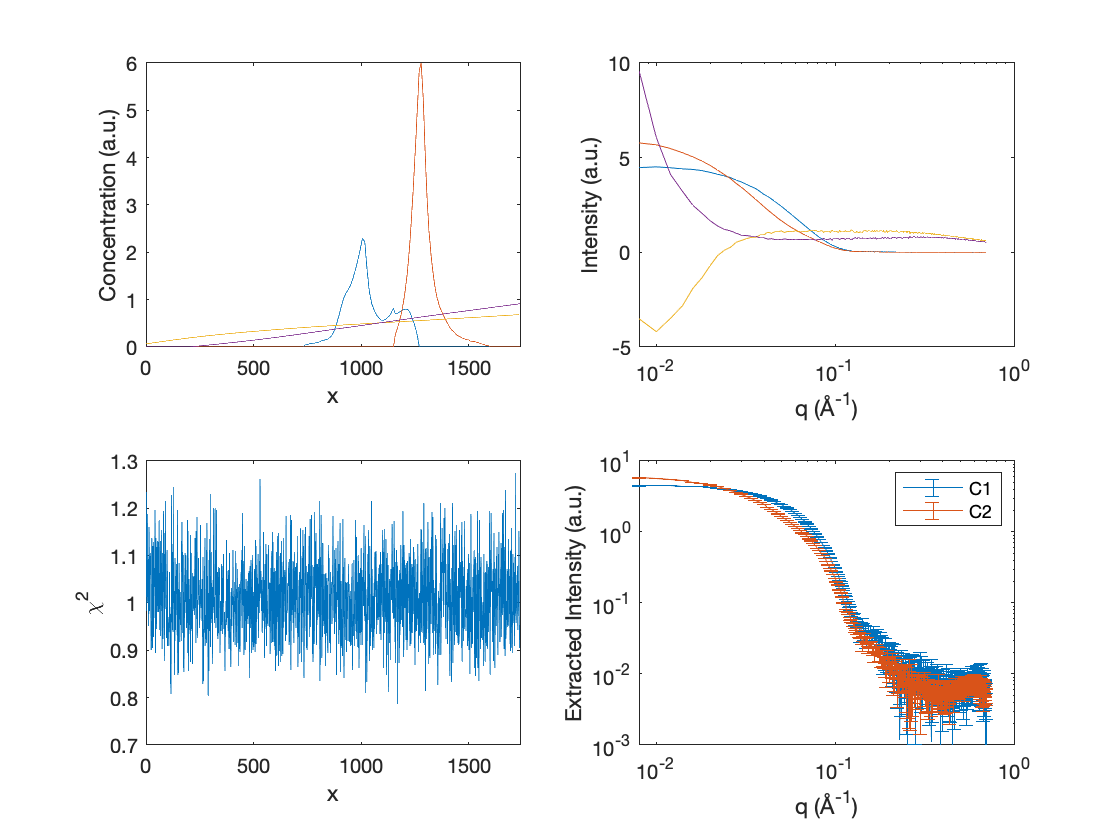

figure(1);clf;
subplot(2,2,1);
plot(M1.concentrations);
set(gca,'Xlim',[0,1738]);xlabel('x');ylabel('Concentration (a.u.)');
subplot(2,2,2);
semilogx(q,M1.profiles);
xlabel('q (Å^{-1})');ylabel('Intensity (a.u.)');
subplot(2,2,3);
plot(mean(resid.^2,1));
set(gca,'Xlim',[0,1738]);xlabel('x');ylabel('\chi^2');
subplot(2,2,4);
errorbar(q,I1,sigma1,'DisplayName','C1');hold on;
errorbar(q,I2,sigma2,'DisplayName','C2');
set(gca,'XScale','Log','Yscale','Log','Ylim',[1E-3,1E1]);
legend show; xlabel('q (Å^{-1})'); ylabel('Extracted Intensity (a.u.)');